## Reading the First Image

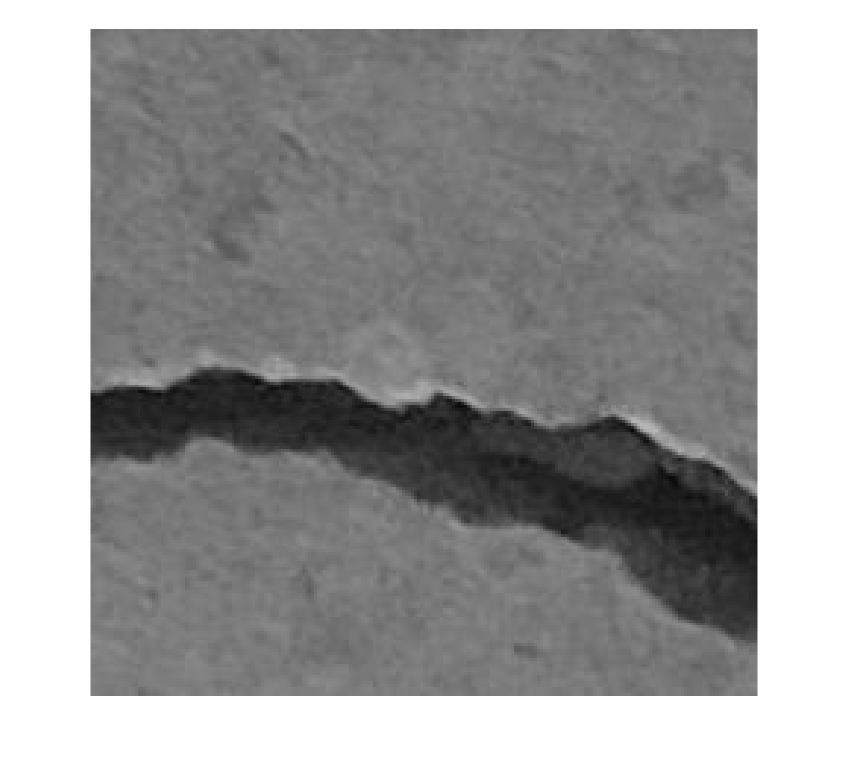

img=im2gray(imread("00187.jpg"));
imshow(img)

## Binarize it to Choose Optimal Value Threshold

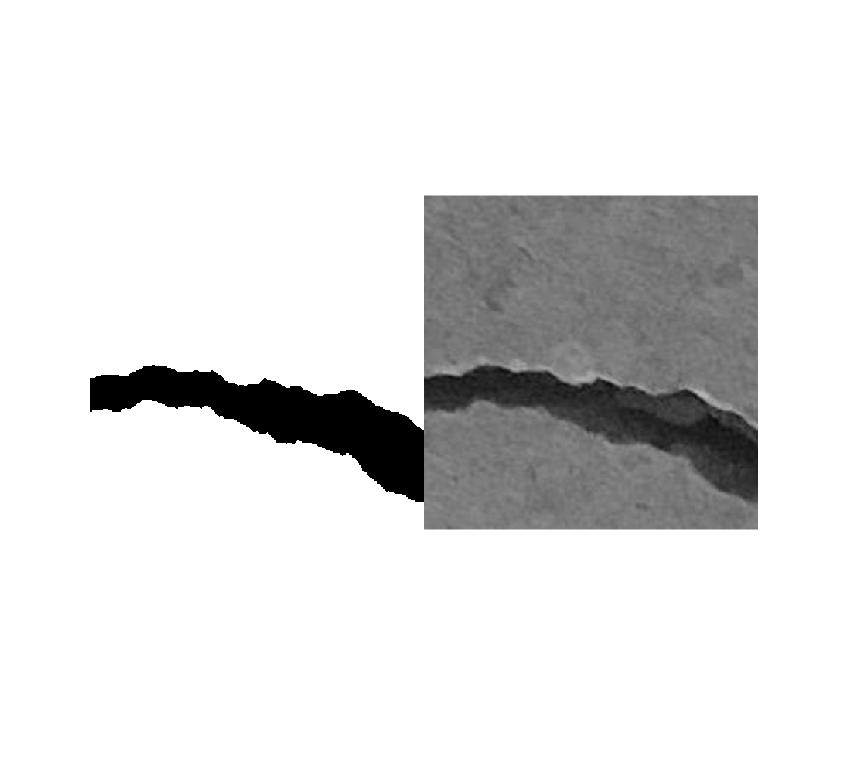

BW = imbinarize(img);
montage({BW, img})

**NOTE :** Binarizing an image turns dark pixels black (false) and light pixels white (true).

**NOTE 2 : imbinarize() **function uses "Otsu's Method". This method finds a threshold value based on the distribution of pixel intensities.

## **Invert the Binarized Image**

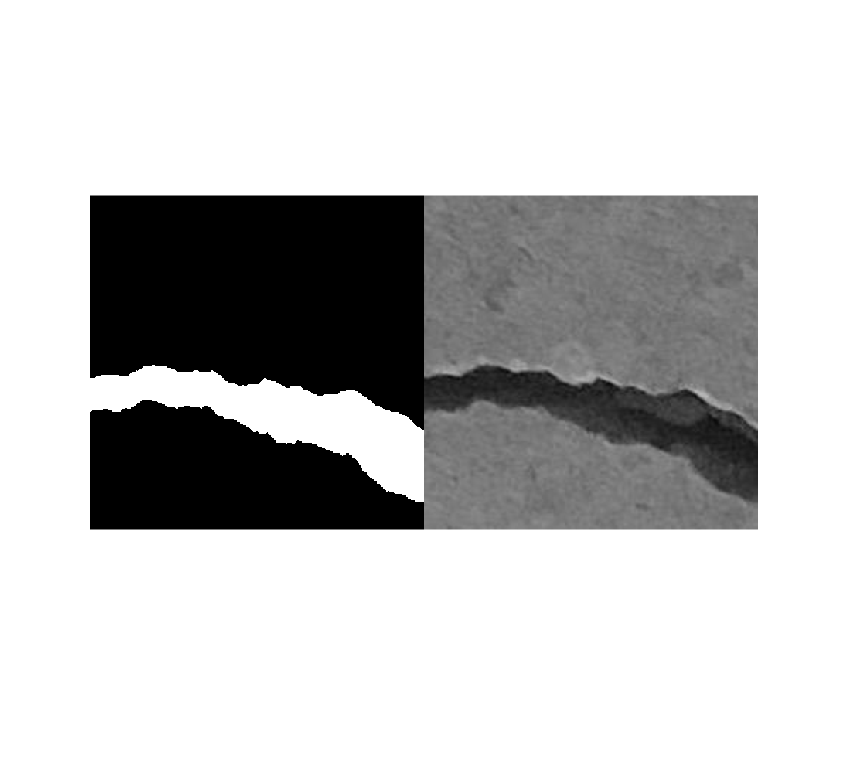

BW = ~BW;
montage({BW, img})

- We are inverting Binarized Image because we are interested in the Crack. So, Crack should be "True". 

## Number of Non-zero Matrix Elements

nnz(BW)

ans = 7846

- In this case, Crack covers 7846 pixels.

## Masking "False" Regions

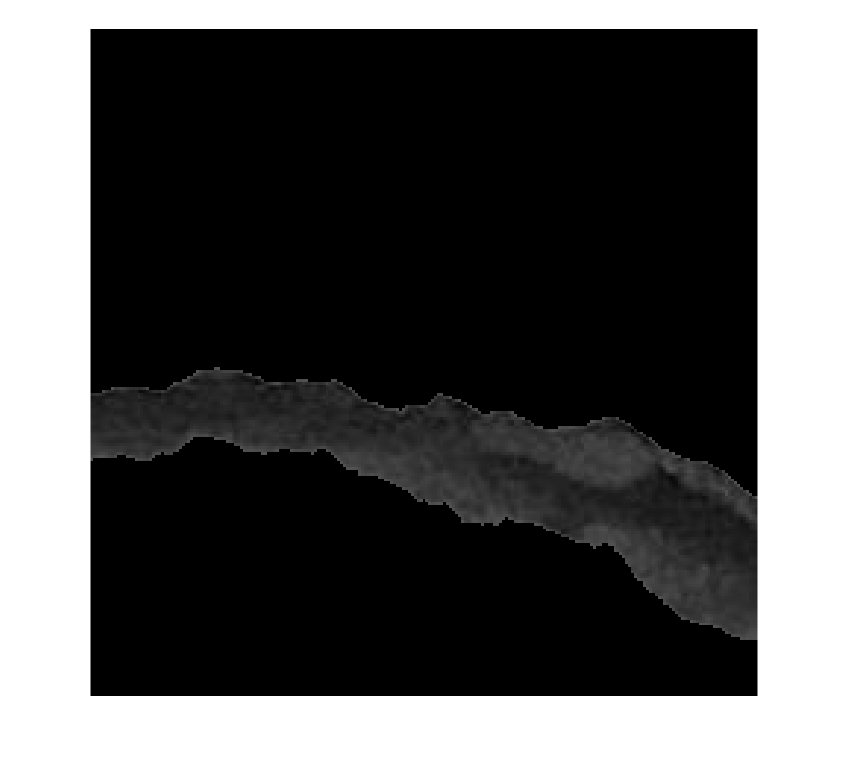

maskedImg = img;
maskedImg(~BW)=0;
imshow(maskedImg)

## Specifying Threshold for Binarize Function

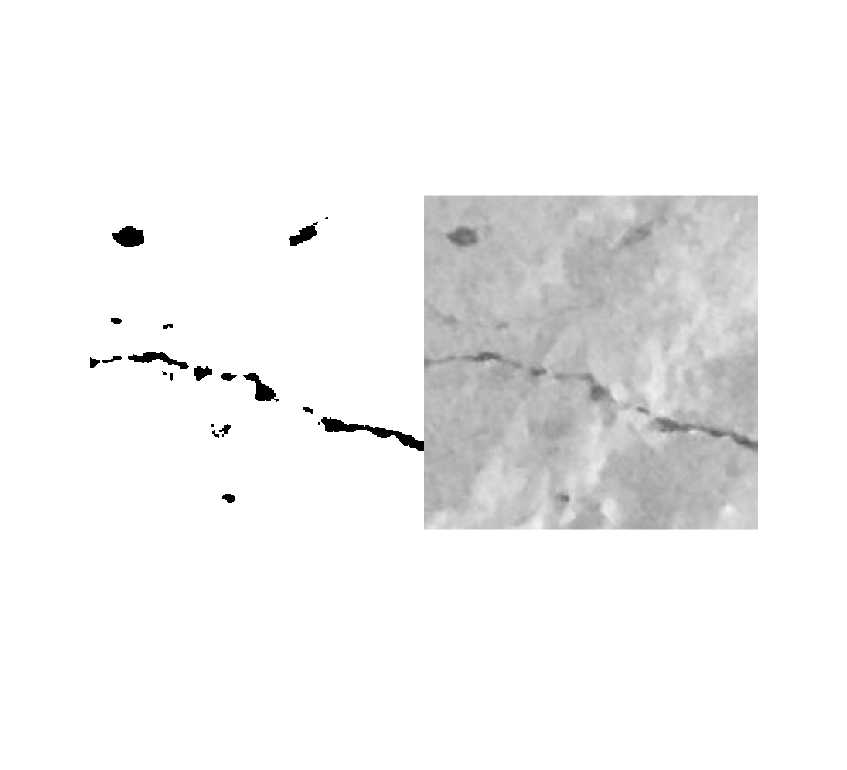

imgSecond=im2gray(imread("00051.jpg"));
BWsec = imbinarize(imgSecond,0.63);
montage({BWsec, imgSecond})

**NOTE:** For this example, "Otsu's Method" doesn't work correctly. Because of that, specifying our own threshold can be better approach.

## Second Example for Specifying Threshold

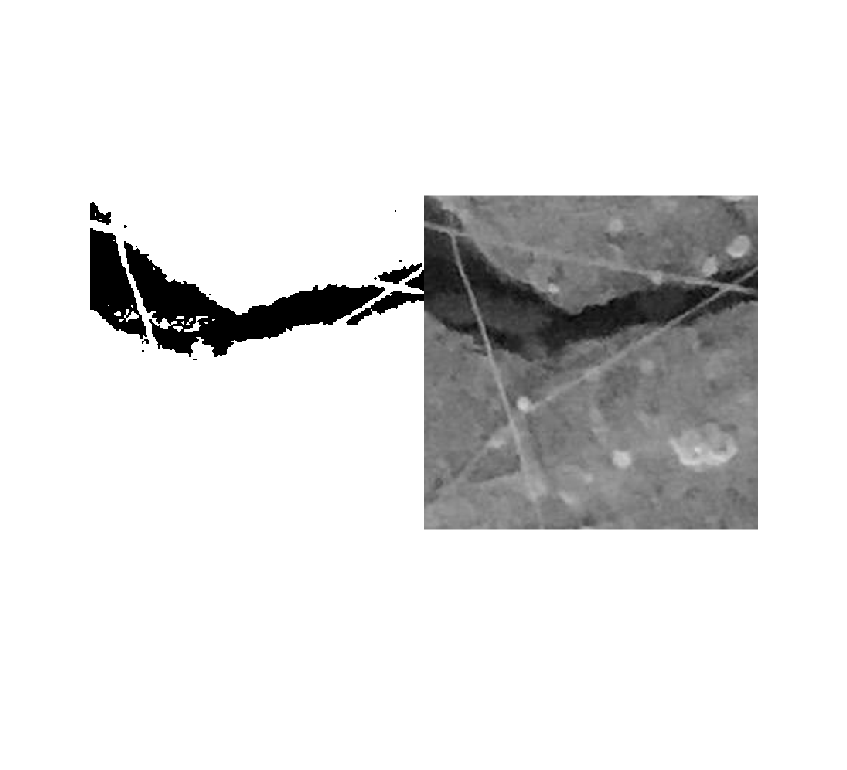

imgThird=im2gray(imread("00161.jpg"));
BWthird = imbinarize(imgThird,0.265);
montage({BWthird, imgThird})

## Using "Adaptive" for Capture All Of The Rice

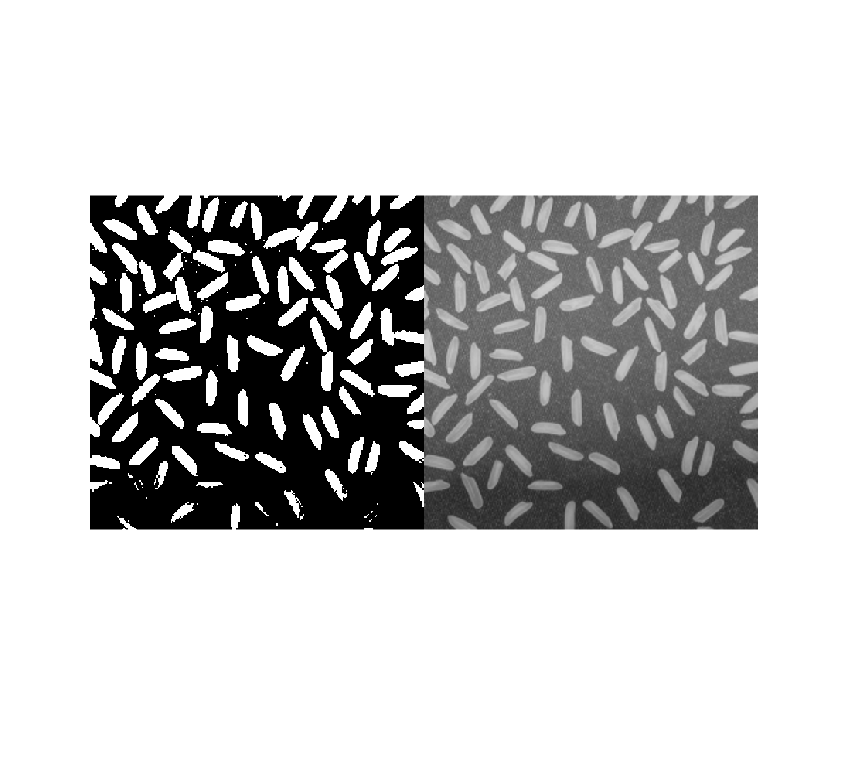

imgRice = imread("rice.png");
BWriceNotAdaptive = imbinarize(imgRice);
BWriceAdaptive = imbinarize(imgRice, "adaptive");
montage({BWriceNotAdaptive,imgRice})

- Bottom part of rice is missing in binarized image. Because this image has uneven illumination.

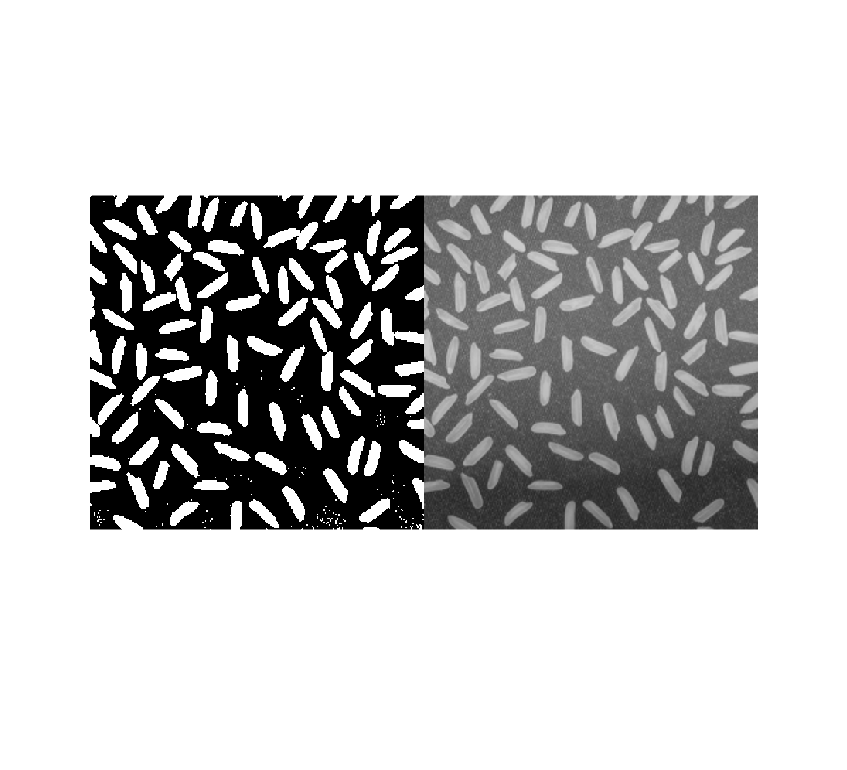

montage({BWriceAdaptive,imgRice})

- Captured all of the rice with "Adaptive" method.

- Adaptive Thresholding calculates local average intensity.

**NOTE:** We did not convert the binarized image because the foreground objects are the high intensity grains. So, it's already "True".

## Reading Image for Multi Thresholding

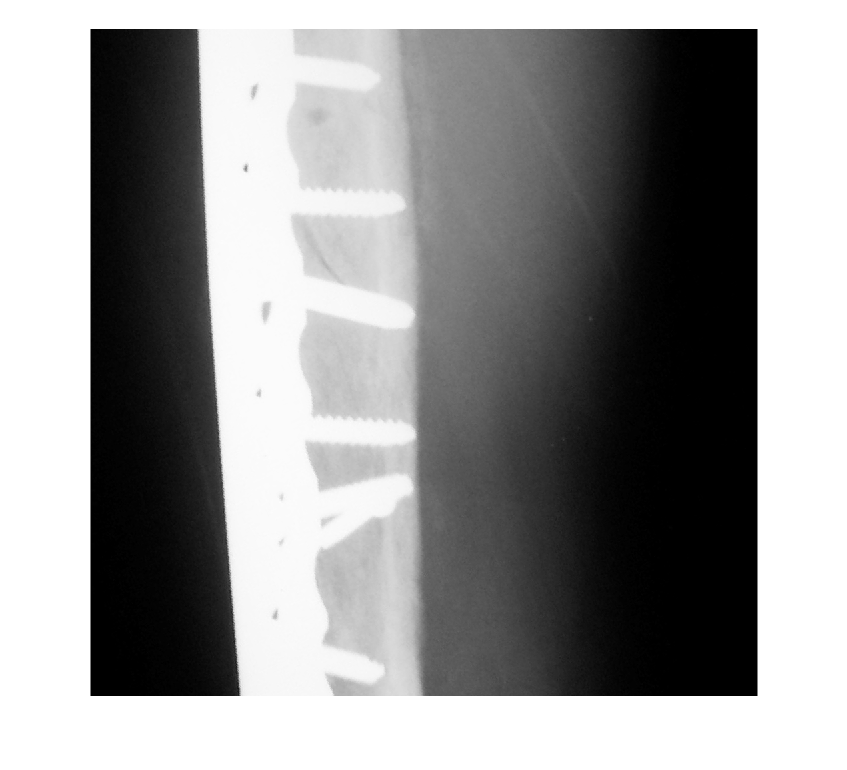

imgXray=imread("armxray.png");
imshow(imgXray)

## Determine Threshold Values

threshValues=multithresh(imgXray,3)

threshValues = 1×3 uint8 row vector
    54   147   223


**NOTE:** You must specify "Number of Thresholds" as second input. For this case, we need 3 thresholds to segment 4 regions.

## Create Multi Labeled Segmented Image

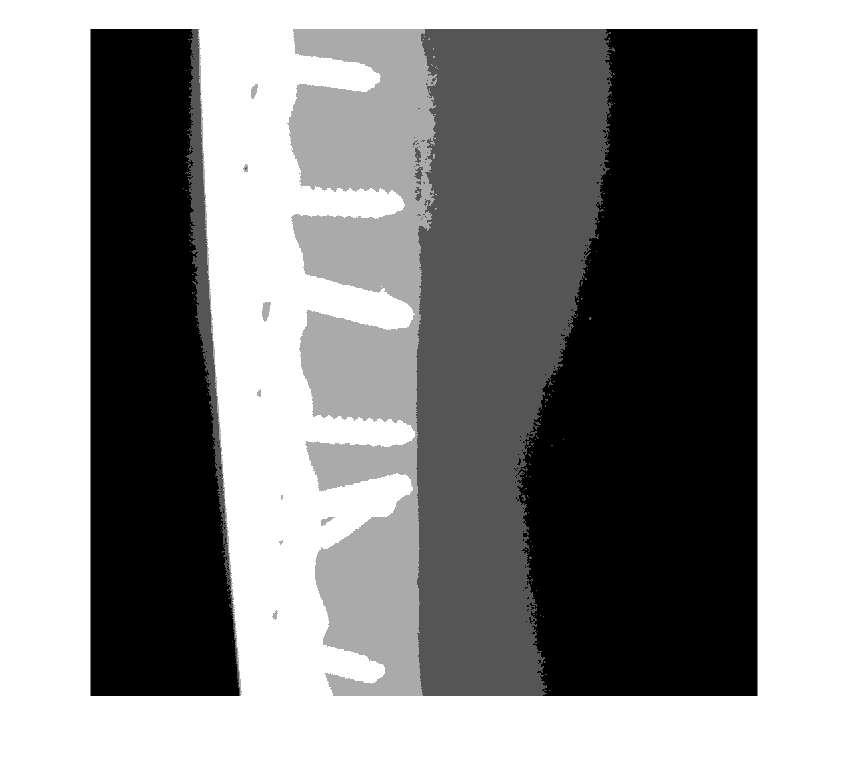

labels = imquantize(imgXray, threshValues);
imshow(labels,[])

**NOTE** : "Labels" is type double. So, you can not view it in its current form. We are using "[]" to use full range of values.

## Isolate Individual Regions

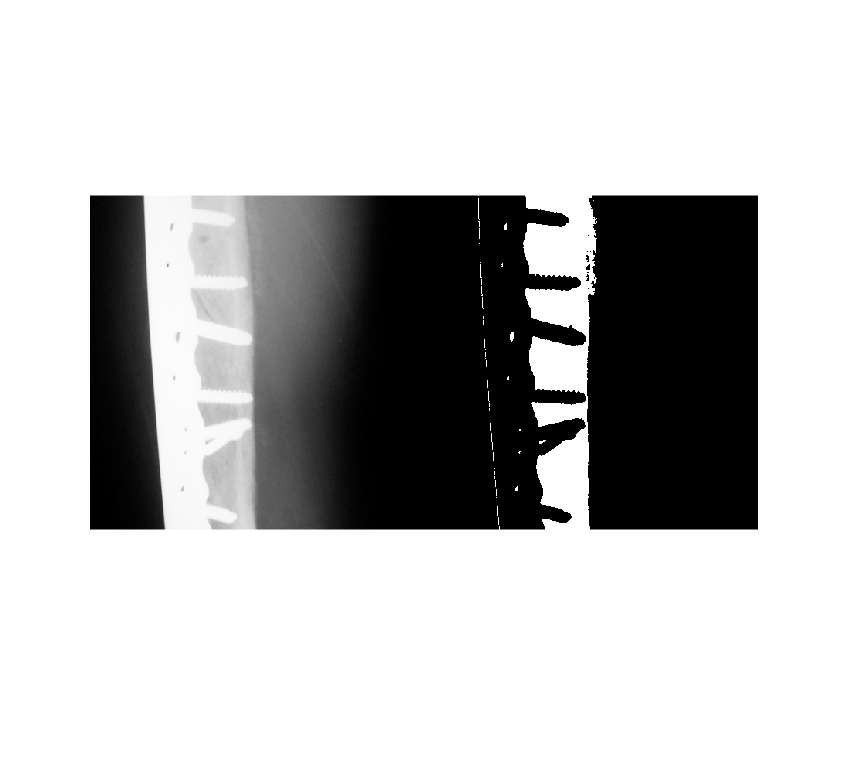

label3 = labels==3;
montage({imgXray,label3})

- For this case we isolated the third label. Which is the "bone".